**Image Histogram Matchin**

%imRef = im2gray(imread("00155.jpg"));
%imshow(imRef)
%imhist(imRef)
%imRef2 = im2gray(imread("00175.jpg"));
%imshow(imRef2)
%imhist(imRef2)  

refImg = im2gray(imread("00004.jpg"));
newImg = im2gray(imread("00143.jpg"));
refThresh = graythresh(refImg)

refThresh = 0.4510

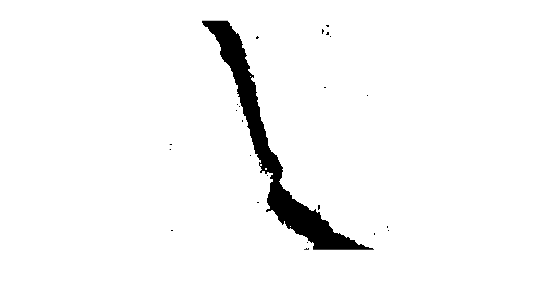

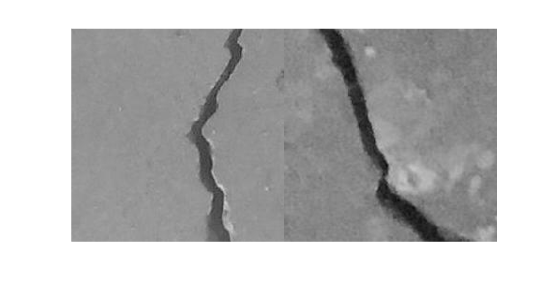

newImgBW = imbinarize(newImg,refThresh);
imshow(newImgBW)

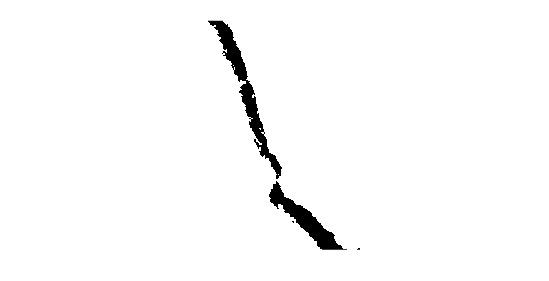

imgMatch = imhistmatch(newImg,refImg,256);
matchImgBW = imbinarize(imgMatch,refThresh);

imshow(matchImgBW)

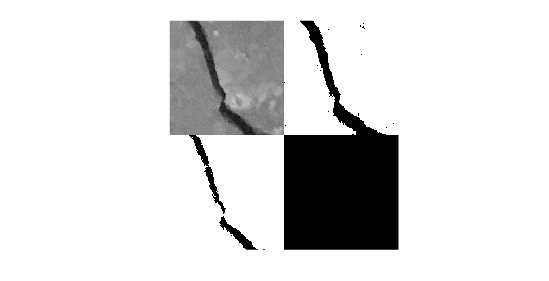


montage({newImg, newImgBW, matchImgBW})